# Gonna use this for testing concepts from the dynamics book

## Use state space

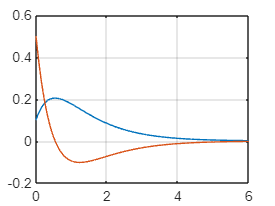

A = [-1,-1; 6.5, 0];
B = [1,1;1,0];
C = eye(2);
D = zeros(2);
syms s;
%system = ss(A,B,C,D,1);
Gs  = C*(s*eye(2)-A)^-1*B +D;
step(A,B,C,D,1)
grid
title('Step Response Plots(u_1=Unit-Step Input, u_2=0)')
xlabel('t'); ylabel('Outputs');

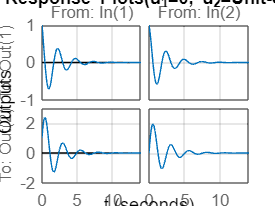


impulse(A,B,C,D)
grid
title('Impulse Response Plots(u_1=0, u_2=Unit-Step Input)')
xlabel('t'); ylabel('Outputs');

%%

%%another mass spring damper system

close all
clear
clc
%%mx'' + bx' + kx =0
t =0:0.01:6;
k =2;
m =1;
b =3;
A = [0, 1;-k/m, -b/m];
B = zeros(2,1);
C = eye(2);
D = zeros(2,1);
x0=[0.1;0.5];
[y,x,t]=initial(A,B,C,D,x0,t);
plot (t, y(:,1), t,y(:,2))
grid

clear
clc
close all

t = 0:0.1:200;
k1= 30;
k2= 60;
m1=10;
m2=20;
b = 20;
alpha=10;

A1= [0, 1,0,0; -(k1+k2)/m1, -b/m1, k2/m1, b/m1; 0,0,0,1; k2/m2, b/m2, -k2/m2, -b/m2];
B1= [0;0;0;alpha/m2];
C1=[1,0,0,0; 0,0,1,0];
D1= zeros(2,1);
system1 = ss(A1,B1,C1,D1)

system1 =
 
  A = 
       x1  x2  x3  x4
   x1   0   1   0   0
   x2  -9  -2   6   2
   x3   0   0   0   1
   x4   3   1  -3  -1
 
  B = 
        u1
   x1    0
   x2    0
   x3    0
   x4  0.5
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


[y,t]  = step(system1)

y =          0         0
    0.0066    0.0269
    0.0450    0.0966
    0.1224    0.1985
    0.2258    0.3252
    0.3378    0.4671
    0.4449    0.6106
    0.5376    0.7414
    0.6087    0.8462
    0.6523    0.9152


t =          0
    0.3477
    0.6954
    1.0431
    1.3908
    1.7385
    2.0862
    2.4339
    2.7816
    3.1293


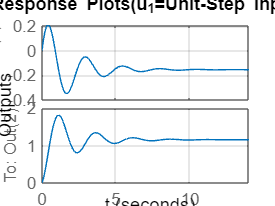

z1 = y(:,1);
z2 = y(:,2);
subplot(3,1,1)
plot(t,z1)
ylabel ('z1')
subplot(3,1,2)
plot(t,z2)
ylabel ('z2')
subplot(3,1,3)
plot(t,z1-z2)

ylabel ('z1-z2')
